% Clear Workspace
clear all

% Read STL File
stl1 = stlread("Test Objects\Box.STL");

% Create UniformSliceGeneratorObject
uSGO1 = FlatUniformSliceGenerator(stl1, 0.1)

uSGO1 =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [12×3 double]
       numOfElements: 12
              points: [8×3 int64]
      sliceThickness: 0.1000


test = uSGO1.getElementData(1)

test =      0   100   100
     0   100     0
     0     0   100


[sliceFlag, X, Y, Z] = uSGO1.getSlicePoint(test(1,:), test(2,:), 50)

sliceFlag = 1

X = 0

Y = 100

Z = 50

scatter3(test(:,1), test(:,2), test(:,3))
xlabel('x')
ylabel('y')
hold on
scatter3(X, Y, Z)
[sliceFlag, X, Y, Z] = uSGO1.getSlicePoint(test(2,:), test(3,:), 50)

sliceFlag = 1

X = 0

Y = 50

Z = 50

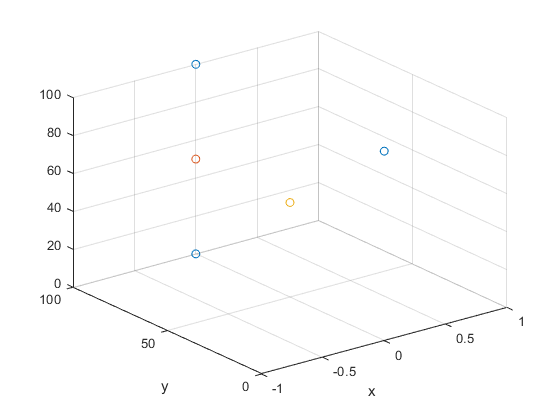

scatter3(X, Y, Z)